# ACC State Abstraction

clear;
close all;
bdclose('all');
addpath('data')

## Load data

Load simulation data from the MAT files

% myFolder = "/Users/jiayangsong/Documents/git/AI-CPS-Ensemble/ACC/data";
% myFolder = "F:\CPS\AI-CPS-Ensemble\ACC\data";
myFolder = "/home/momentumlab/Documents/git/AI-CPS-Ensemble/ACC/data";


% check if folder path is valid
if ~isfolder(myFolder)
    errorMessage = sprintf('Error: The following folder does not exist:\n%s', myFolder);
    uiwait(warndlg(errorMessage));
    return;
end

% load all .MAT files under determined folder
filePattern = fullfile(myFolder, '*.mat');
matFiles = dir(filePattern);
[fileNumber, ~]= size(matFiles);
data = cell(fileNumber, 1);         % cell array to hold all simulation results

for k = 1:length(matFiles)
  baseFileName = matFiles(k).name;
  fullFileName = fullfile(myFolder, baseFileName);
  fprintf(1, 'Now reading %s\n', fullFileName);
  data{k} = load(fullFileName).results;
end

Now reading /home/momentumlab/Documents/git/AI-CPS-Ensemble/ACC/data/ACC_MPC_PH_100_robust_0.mat
Now reading /home/momentumlab/Documents/git/AI-CPS-Ensemble/ACC/data/ACC_MPC_PH_100_robust_1.mat
Now reading /home/momentumlab/Documents/git/AI-CPS-Ensemble/ACC/data/ACC_MPC_PH_10_robust_0.mat
Now reading /home/momentumlab/Documents/git/AI-CPS-Ensemble/ACC/data/ACC_MPC_PH_10_robust_1.mat
Now reading /home/momentumlab/Documents/git/AI-CPS-Ensemble/ACC/data/ACC_MPC_PH_50_robust_0.mat
Now reading /home/momentumlab/Documents/git/AI-CPS-Ensemble/ACC/data/ACC_MPC_PH_50_robust_1.mat
Now reading /home/momentumlab/Documents/git/AI-CPS-Ensemble/ACC/data/ACC_MPC_PH_5_robust_0.mat
Now reading /home/momentumlab/Documents/git/AI-CPS-Ensemble/ACC/data/ACC_MPC_PH_5_robust_1.mat
Now reading /home/momentumlab/Documents/git/AI-CPS-Ensemble/ACC/data/ACC_RL_ACC-DDPG-03-May-0.2-0.8-0.01.mat
Now reading /home/momentumlab/Documents/git/AI-CPS-Ensemble/ACC/data/ACC_RL_ACC-DDPG-29-Apr-0.5-0.5-0.01.mat
Now reading /h

## Abstract MDP Construction

### Concrete MDP Concatenation

Combine collected experience from each controller

% combine data from all simulations
mdpData = {};
for i = 1:length(data)
    mdpData = cat(2,mdpData, data{i}.data);
end

% construct concrete state, action, reward space
[mdpSpace, abMdpSpace] = deal(cell2mat(mdpData'));
numSample = length(mdpSpace);
stateSpace = mdpSpace(:, 1:4);
actionSpace =mdpSpace(:,5);

% number of unique concrete states and actions
numConcreteState = length(unique(stateSpace(:,1:4),'rows'));
numConcreteAction = length(unique(actionSpace));

fprintf("Number of samples: %i" + ...
    "\nNumber of concrete states: %i" + ...
    "\nNumber of concrete actions: %i", length(mdpSpace), numConcreteState, numConcreteAction);

Number of samples: 7442000
Number of concrete states: 6014269
Number of concrete actions: 5287459

% concreteTranSpace = cat(2, mdpSpace(1:end-1,1:5), mdpSpace(2:end,1:4));
length(unique(concreteTranSpace(:,1:5),'rows'))

ans = 6106552

### Floating Point Quantization

% abMdpSpace = round(abMdpSpace, 4);
% abActionSpace = round(actionSpace, 4);
% 
% fprintf("Number of states after quantization: %i" + ...
%     "\nNumber of actions after quantization: %i", length(unique(abMdpSpace(:,1:4),'rows')), length(unique(abActionSpace)));

### Action aggregation

**Unifromaly** partiion the action space

Collected data: d_rel, d_safe, v_target, v_ego, a_ego, d_reward, v_reward

The partition interval is:  actionInverval = actionRange * 5% = 0.25

% abstract action space
actionMin = min(actionSpace);
actoinMax = max(actionSpace);
actionInverval = (actoinMax - actionMin)*0.1;

actionTreshold = [[-inf,actionMin:actionInverval:actoinMax];[actionMin:actionInverval:actoinMax, +inf]]';
actionTreshold = mat2cell(actionTreshold, ones(1,length(actionTreshold)),2);

for i = 1:length(actionTreshold)
    temp = num2cell(actionTreshold{i});
    [lower, upper] = temp{:};
    abActionSpace((actionSpace>lower) & (actionSpace <= upper)) = i;
end

% substitute concrete action space with abstract action space
abMdpSpace(:, 5) = abActionSpace;
numAbAction = length(unique(abActionSpace));

fprintf("Split action space with interval: %.2f \nNumber of abstracted actions: %i", actionInverval, numAbAction);

Split action space with interval: 0.50 
Number of abstracted actions: 11

### Reward Clustering

Cluster concrete states into abstract clusters based on rewards

Split reward space into multiple intervals. Each interval shoud contain a minimum number of concrete states. 

Two clusteriing creteria: **Minimum distance**,** Minimum Points**

- minDistance = Reward range * A%

- minPoints = Number of concrete state *B%

% this section is only used for corret the distance reward
d_reward = abMdpSpace(:,6);
d_error = abMdpSpace(:,1) - abMdpSpace(:,2);
d_reward(d_error>=0) = tanh(d_error(d_error>=0));
d_reward(d_error<0) = tanh(d_error(d_error<0)*4);
abMdpSpace(:,6) = d_reward;
mdpSpace(:,6) = d_reward;
rewardSpace = abMdpSpace(:,end-1:end);
concreteRewardSpace = cat(2, rewardSpace, mean(rewardSpace,2));

% d_reward = abMdpSpace(:,6);
% d_error = abMdpSpace(:,1) - abMdpSpace(:,2);
% d_reward(d_error>=0) = tanh(d_error(d_error>=0)/8);
% d_reward(d_error<0) = tanh(d_error(d_error<0)/1.5);
% abMdpSpace(:,6) = d_reward;
% mdpSpace(:,6) = d_reward;
% rewardSpace = abMdpSpace(:,end-1:end);
% concreteRewardSpace = cat(2, rewardSpace, mean(rewardSpace,2));

% x = -10:0.1:20;
% y = zeros(length(x),1);
% y(x>=0) = tanh(x(x>=0)/8);
% y(x<0) = tanh(x(x<0)/1.5);
% plot(x,y);

% minimum distance and minimum number for a cluster
dimReward = size(rewardSpace);       % dimension of the reward
rewardIndex = zeros(dimReward);
rewardInterval = cell(1,dimReward(2));

% percentage parameter to compute minimum distance and minimum number of states
RewardMinDistPerc = [0.001,0.001];
RewardMinNumPerc = [0.005, 0.005];

% abstraction on each reward dimension
for i = 1:dimReward(2)
    reward = rewardSpace(:,i);
    RewardMinDist = (max(reward) - min(reward))*RewardMinDistPerc(i);
    RewardMinNum = round(numSample*RewardMinNumPerc(i));
    
    [index, interval] = RewardClustering(reward, RewardMinDist, RewardMinNum);
    rewardIndex(:,i) = index;
    rewardInterval{i} = interval;
end

% unique abstract reward index pair (only for rewardDimension >=2)
[C,~,ic] = unique(rewardIndex, 'rows');
% look-up table to find index of abstract reward
rewardToIndexTable = cat(2,C,(1:length(C))'); 
rewardIndex(:, end+1) = ic;
abMdpSpace(:,6:8) = rewardIndex;
fprintf("Number of abstract state after reward clustering: %i", length(unique(abMdpSpace(:,8))));

Number of abstract state after reward clustering: 2297

**Compute average reward for each abstract state**

abStateNum = length(unique(abMdpSpace(:,8)));
abAvgReward = ones(abStateNum,3);
abRewardSpace = zeros(numSample,3);
abMdpSpace(:,end+1) = zeros(numSample,1);

for i = 1:abStateNum
    abAvgReward(i,1) = mean(rewardSpace(rewardIndex(:,3)==i,1));
    abAvgReward(i,2) = mean(rewardSpace(rewardIndex(:,3)==i,2));
    abAvgReward(i,3) = mean(rewardSpace(i, 1:2));
    abRewardSpace(abMdpSpace(:,8)==i, 1) = abAvgReward(i,1) ;
    abRewardSpace(abMdpSpace(:,8)==i, 2) = abAvgReward(i,2) ;
%     abRewardSpace(abMdpSpace(:,8)==i, 3) = abAvgReward(i,3) ;
    abMdpSpace(abMdpSpace(:,8)==i, 9) = abAvgReward(i,3);
end

abRewardSpace(:,3) = mean(abRewardSpace(:,1:2),2);

x1 = mdpSpace(:,6)+mdpSpace(:,7);
x2 = abMdpSpace(:,9);

% x1 = randsample(x1,2000);
% x2 = randsample(x2,2000);
% h = histogram(x1,50);

[h,p,ks2stat] = kstest2(x1,x2,'Alpha',0.05);
disp([h,p,ks2stat]);

    1.0000         0    0.5920



[R,P] = corrcoef(x1,x2);
disp(R);

    1.0000    0.3561
    0.3561    1.0000



## Abstraction Error 

velError= abs((concreteRewardSpace(:,2) - abRewardSpace(:,2)));
distError = abs((concreteRewardSpace(:,1) - abRewardSpace(:,1)));
overallErro = abs((concreteRewardSpace(:,3) - abRewardSpace(:,3)));

% fprintf("Velocity: Mean: %f", )

max(overallErro)

ans = 0.1113

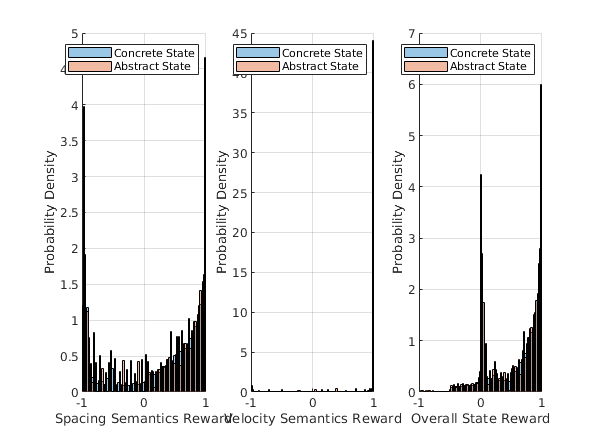

nbins = 100;

figure;
subplot(1,3,1);
hold on 
h1 = histogram(concreteRewardSpace(:,2), nbins,'FaceAlpha',0.4, 'Normalization','pdf');
h2 = histogram(abRewardSpace(:,2), nbins,'FaceAlpha',0.4,'Normalization','pdf');
hold off
grid on;
xlim([-1, 1]);
legend("Concrete State", "Abstract State");
% title("PDF: Velocity Semantics Reward");
xlabel('Spacing Semantics Reward') ;
ylabel('Probability Density') ;

% figure;
subplot(1,3,2);
hold on 
h1 = histogram(concreteRewardSpace(:,1),nbins, 'FaceAlpha',0.4, 'Normalization','pdf');
h2 = histogram(abRewardSpace(:,1),nbins, 'FaceAlpha',0.4,'Normalization','pdf');
hold off
grid on;
xlim([-1, 1]);
legend("Concrete State", "Abstract State");
% title("PDF: Reward");
xlabel('Velocity Semantics Reward') ;
ylabel('Probability Density') ;

subplot(1,3,3);
hold on 
h1 = histogram(concreteRewardSpace(:,3),nbins, 'FaceAlpha',0.4, 'Normalization','pdf');
h2 = histogram(abRewardSpace(:,3),nbins, 'FaceAlpha',0.4,'Normalization','pdf');
hold off
grid on;
xlim([-1, 1]);
legend("Concrete State", "Abstract State");
% title("PDF: Reward");
xlabel('Overall State Reward') ;
ylabel('Probability Density') ;
pos = get(gcf, 'Position');
set(gcf, 'Position',pos+[0 -100 10 0.1])

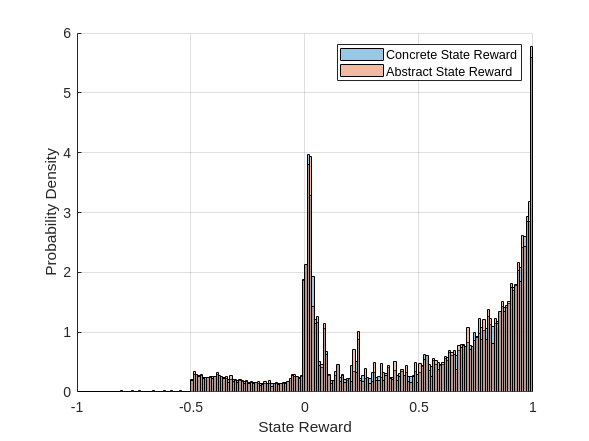

figure;
% subplot(1,2,2);
hold on 
abRewardSpace(:,3) = mean(abRewardSpace(:,1:2),2);
h1 = histogram(concreteRewardSpace(:,3), 'FaceAlpha',0.4, 'Normalization','pdf');
h2 = histogram(abRewardSpace(:,3), 'FaceAlpha',0.4,'Normalization','pdf');
hold off
grid on;
xlim([-1, 1]);
legend("Concrete State Reward", "Abstract State Reward");
% title("PDF: Reward");
xlabel('State Reward') ;
ylabel('Probability Density') ;

[h,p,ks2stat] = kstest2(h1.Values,h2.Values,'Alpha',0.02);
disp([h,p,ks2stat]);

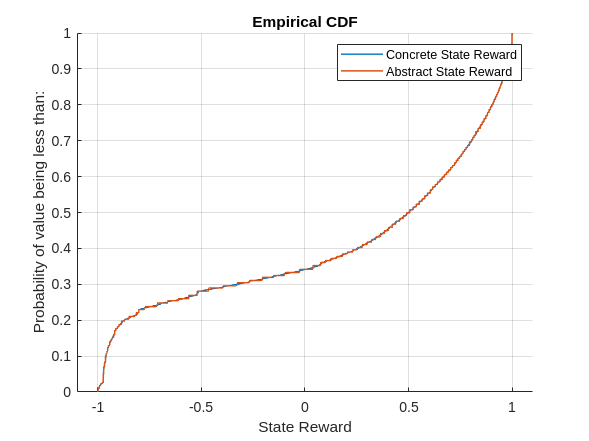

x1 = concreteRewardSpace(:,2);
x2 = abRewardSpace(:,2);

figure;
hold on 
h1 = cdfplot(x1);
h2 = cdfplot(x2);
h1.LineWidth = 1;
h2.LineWidth = 1;
hold off
grid on;
xlim([-1.1, 1.1]);
legend("Concrete State Reward", "Abstract State Reward");
% title("CDF: Reward");
xlabel('State Reward') ;
ylabel('Probability of value being less than:') ;

## Abstract Transition Construction

Partition existing abstract state further w.r.t. transitions

if two abstract state have identical distribution under same action, they can be considered as one abstract state, vice versa.

% abstract transition space
abstractState = abMdpSpace(:,8);
abstractTran = cat(2, abMdpSpace(:,[8,5]), [abMdpSpace(2:end,8);0]);
abstractTran = cat(2, abstractTran, [abMdpSpace(2:end,9);0]);

% unique state-action pair
[C,ia,ic] = unique(abstractTran(:,1:2), 'rows');
abstractTran = cat(2, abstractTran, ic);
numStateActionPair = length(C);

% remove the last state with no transition
samplePerSim = data{1}.sample_each_sim+1;   % num of samples per simulation
abstractTran = abstractTran(~rem(1:numSample,samplePerSim)==0,:);

% state-action -> next state
tranTable = cat(2,C,zeros(numStateActionPair,3));
abstractTranReward = cat(2, concreteRewardSpace(~rem(1:numSample,samplePerSim)==0,:), zeros(length(abstractTran), 4));
abstractTranReward(:,4) = abstractTran(:,5);

% compute average of the next possible states
for i = 1: numStateActionPair
    tranTable(i,3) = mean(abstractTran(abstractTran(:,5)==i, 4));
end

fprintf("Number of abstract transition: %i", max(abstractTran(:,5)));

Number of abstract transition: 17797

for i = 1: numStateActionPair
    abstractTranReward(abstractTranReward(:,4)==i,5) = mean(abstractTranReward(abstractTranReward(:,4)==i,1));
    abstractTranReward(abstractTranReward(:,4)==i,6) = mean(abstractTranReward(abstractTranReward(:,4)==i,2));
    abstractTranReward(abstractTranReward(:,4)==i,7) = mean(abstractTranReward(abstractTranReward(:,4)==i,3));
end

tranDistError = abs(abstractTranReward(:,1) - abstractTranReward(:,5));
tranVelError = abs(abstractTranReward(:,2) - abstractTranReward(:,6));
tranOverallError = abs(abstractTranReward(:,3) - abstractTranReward(:,7));

median(tranOverallError)

ans = 9.4982e-04

mean(tranOverallError)

ans = 0.0033

max(tranOverallError)

ans = 0.1207

figure;
hold on 
histogram(abstractTran(:,5), 'FaceAlpha',0.4);
hold off
grid on;
% xlim([-2, 2]);
% legend("Concrete State Reward", "Abstract State Reward");
title("Abstract Transition Distribution");
xlabel('Abstract Transition') ;
ylabel('Number of occurence') ;

Up to now, we have the look up table for abstract state and abstract transition

**The reward of an abstract state =  average reward of all concrete state inside **

**The reward of a abstract transition = average reward of all possible next abstract state**

## Convert a concrete state to abstract state

GIven a concrete state we can convert it to an abstract state with reward.

With an abstract action, we can estimate the transition to next possible states.

testInput= mdpData{1,1};
testInput = testInput(1,:);
testReward = rewardSpace(1,:);

% upper bound of all action intervals
actionUB = cell2mat(actionTreshold);
actionUB = actionUB(:,2);
abAction = find(actionUB >= testInput(5), 1, 'first');

rewardUB_1 = cell2mat(rewardInterval{1}');
rewardUB_1 = rewardUB_1(:,2);
rewardUB_2 = cell2mat(rewardInterval{2}');
rewardUB_2 = rewardUB_2(:,2); 

abReward_1 = find(rewardUB_1 >= testReward(1), 1, 'first');
abReward_2 = find(rewardUB_2 >= testReward(2), 1, 'first');

abState = rewardToIndexTable(rewardToIndexTable(:,1)==abReward_1 & rewardToIndexTable(:,2)==abReward_2,3);
abTranReward = tranTable(tranTable(:,1)==abState & tranTable(:,2)==abAction,3);
if isempty(abTranReward)
    abTranReward = 0;
end


## Combine data & Establish abstract model

Combine results from abstract states and abstract transition to build up the complete abstract model

% save abstract states and transitions
controllerName = strings(fileNumber,1);
for i = 1:fileNumber
    tempName = matFiles(i).name;
    controllerName(i) = tempName(1:end-4);
end

name = "ACC_abstract_model";
mdpVarName = ["d_rel", "d_safe", "v_target", "v_ego", "a_ego", "d_reward", "v_reward"];
abMdpVarName = ["d_rel", "d_safe", "v_target", "v_ego", "ab_action", "reward_index_1", "reward_index_2", 'ab_state', "ab_state_reward"];
tranVarName = ["curret state", "action", "next state", "avg reward of next possible states", "transition index"];

abModel= struct('name', name,...
                'controllerName', controllerName,...
                'actionUB', actionUB,...
                'rewardUB_1', rewardUB_1,...
                'rewardUB_2', rewardUB_2,...
                'rewardToIndexTable', rewardToIndexTable,...
                'tranTable', tranTable);

**Collect abstract state and tranitiosns for later controller selection**

% abstract state and transition from identical input for comparison
identicalNum = 15;
identicalSimNum = 1000;
[compareState, compareTran] = deal(cell(identicalNum,1));
compareStateData = abstractState(identicalNum*identicalSimNum*samplePerSim:end);
tempTran = abstractTran(:,5);
compareTranData = (tempTran(identicalNum*identicalSimNum*(samplePerSim-1):end));

for i = 1:identicalNum
    compareState{i} = compareStateData(identicalSimNum*samplePerSim*(i-1)+1:identicalSimNum*samplePerSim*i);
    compareTran{i} = compareTranData((identicalSimNum*samplePerSim-1)*(i-1)+1:(identicalSimNum*samplePerSim-1)*i);
end

compareName = controllerName(fileNumber-identicalNum+1:end);
abCompare= struct('name', {compareName},...
                'state', {compareState},...
                'transition', {compareTran});

#### Data saving

Save abstract model resutls (data) into MAT file.

The MAT file contains a cell array with structure arrays as elements, each structure array contains an abstract model with following fields:

- raw_data: original simulation results, no data processing applied

- abs_state: abstract state

- abs_tran: abstract transition

% save results in a MAT file
is_save = false;

if is_save
    save(name+".mat", "abModel");
    disp(name + " saved");

    save("ACC_comparison.mat", "abCompare");
    disp("ACC_comparison saved");
end